## Import Data

%% What are B-Spline coefficients for Pmus?
%To do: determine flow index, sort B-spline coefficient groups by flow
%index


clear all
close all
addpath("C:\Users\292636H\OneDrive - Curtin\PhD\Matlab")
addpath("C:\Users\292636H\OneDrive - Curtin\PhD\Matlab\B-MIQP Working Folder\.mat files")
%% Extract Single Breath\load patient data
load('20_breaths_pat_2_brescia_non_asynch.mat')

## Remove pes spikes

%patient specific, determine start and end of each spike
ind_start_spike = [1915,8387];
ind_end_spike = [3037,9556];

dataExtract = structfun(@(x) x([1:ind_start_spike(1),ind_end_spike(1):ind_start_spike(2),ind_end_spike(2):end]),dataExtract,'UniformOutput',false);
dataExtract.pes_filt = dataExtract.pes;

## Filter Pes (but it kind of sucks)

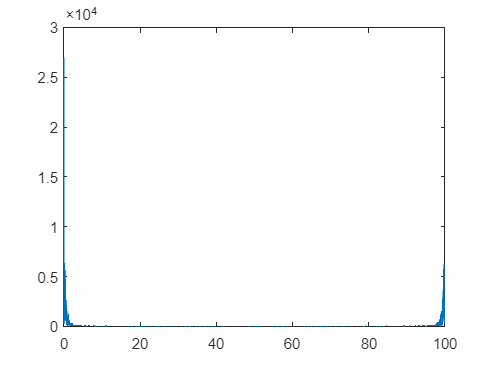


%% Filter Pes Signal
Fs = 100;            % Sampling frequency
dt = 1/Fs;             % Sampling period
n = length(dataExtract.pes);             % Length of signal

%perform fourier transform
fhat = fft(dataExtract.pes);

%determine frequencies
freq = Fs/n*(0:n-1);
%create system variables
sys = frd(fhat,freq,'FrequencyUnit','Hz');

%fft plot
figure()
plot(Fs/n*(0:n-1),abs(fhat),"-")
hold on


%user to enter, what is funadmental frequency of CGO signal?
F_cgo = 1.97;

pes_filt = pesFilterFun(dataExtract,Fs,F_cgo);
%pes_filt = smooth(dataExtract.pes,20);
dataExtract.pes_filt = pes_filt;


start_insp = [1
484
994
1596
2220
2757
3313
3841
4563
5108
5758
6358
6913
7399
7928
8431
8845
9445
10042
10725
11299
11949];
%start_insp = [9128 9382 9640 9901 10122 10431];

## Fit B-splines to Pmus

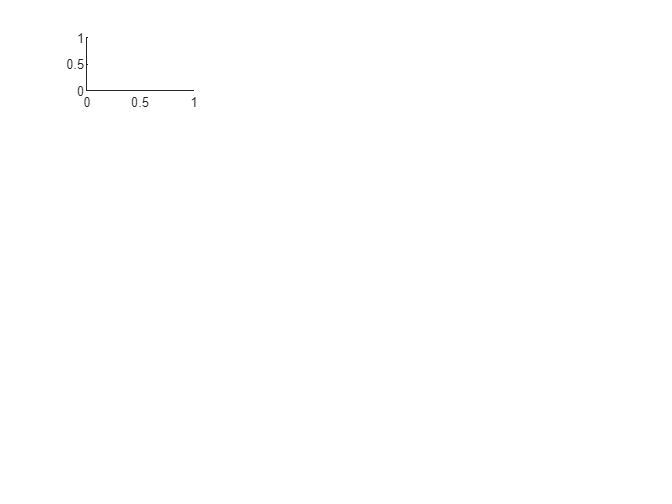

%% Determine start of each patient inspiration
k_soe = find(diff(dataExtract.phase) == -32)+1;
Ecw = 11.43; %chest wall elastance
num_breaths = 20;
dataExtract.PEEP = 6;
%Determine start of each breath
% [pesShiftedEachBreath,pes_filt_shift, pes_shift,Pmus_inv_allBreaths, ...
%     volume_allBreaths, flow_allBreaths, paw_allBreaths, Pmus_inv_raw_allBreaths, phase_allBreaths] ...
%     = startOfInspPatFun(dataExtract,Ecw,num_breaths);

% blank arrays
coeff_bs_norm_array = zeros(20,30);
coeff_bs_array = zeros(20,30);
length_vent_insp_array = zeros(20,1);
insp_length_array = zeros(20,1);
Ti_array = zeros(20,1);
Paw_peak_array = zeros(20,1);
peaks_array = zeros(20,1);
peak_time_array = zeros(20,1);
counter =  1;
i = 1;
X_array = [];
params_array = [];
beta_array = [];
%collect 20 breaths per patient
tiledlayout(5,4)
nexttile

while counter < num_breaths +1

    %if i is less than total number of breaths
    %if i <= length(volume_allBreaths)
        % volume = volume_allBreaths{i};
        % flow = flow_allBreaths{i};
        % paw = paw_allBreaths{i};
        % phase = phase_allBreaths{i};
   for i = 1:20
        volume = dataExtract.vol(start_insp(i):start_insp(i+1));
        flow = dataExtract.flow(start_insp(i):start_insp(i+1));
        paw = dataExtract.pres(start_insp(i):start_insp(i+1));
        phase = dataExtract.phase(start_insp(i):start_insp(i+1));

        %if no end expiratory volume present
        if volume(1) < 500
            %pes = pesShiftedEachBreath{i};
            %pmus = Pmus_inv_allBreaths{i};
            pes = dataExtract.pes(start_insp(i):start_insp(i+1));
            pes = pes - pes(1);
            pmus = pes - (volume/1000*Ecw);
            pmus = pmus - pmus(1);

            % figure()
            % %set(gcf,'Visible','on')
            % plot(pes)
            % hold on
            % plot(paw)
            % plot(pmus)
            % hold off
    
            % prompt = "this right?"
            % ind_prompt = input(prompt)
            % 
            % if ind_prompt ~= 0
            %     flow = flow(ind_prompt:end);
            %     volume = volume(ind_prompt:end);
            %     paw = paw(ind_prompt:end);
            %     phase = phase(ind_prompt:end);
            %     pes = pes(ind_prompt:end);
            %     pmus = pmus(ind_prompt:end);
            % end
            % Peaks + lengths
            [peaks_array(counter,1),peak_time_array(counter,1)] = min(pmus);
            length_vent_insp_array(counter,1) = find(diff(phase) == 32)+1;
            insp_length_array(counter,1) = find(pes<0,1,'last');

            if insp_length_array(counter,1) > length_vent_insp_array(counter,1)
                pes_vent = pes(1:length_vent_insp_array(counter,1));
                insp_length_array(counter,1) = find(pes_vent < 0,1,'last');
            end

            %normalise muscle pressure
            peak_pmus = min(pmus);
            pmus = pmus/peak_pmus;


            %obtain max paw 
            

            % Generate B-Splines, fit only to inspiration


            %length of breath
            length_breath = length(flow)/100;
            %length_breath = length_vent_insp_array(counter,1)/100;
            totalTime = [0.01:0.01:length_breath]; %create time vector equal to length of inspiratory effort

            %create B-Spline model
            Kw = 0.25; %knot width, s
            Tmax = Kw * ceil(length_breath/Kw); %Time span of B-spline functions
            d = 3; %degree of B-splines
            M = Tmax/Kw + d; %number of B-splines
            %M = 10;
            knots = 0:Kw:Tmax; %knot vector
            knots = [0 0 0 knots Tmax Tmax Tmax]; %knot vector adding dummy values at start and end

            %create 2nd order B-spline fucnctions
            phi_2 = zeros(cast(M,"int32"),length(totalTime));
            for idx1 = 1:M
                phi_2(idx1,(1:length(totalTime))) = bspline_basis(idx1,3,knots,totalTime);
            end

            % Model Pmus using B-Splines
            lb = zeros(M,1);
            coeff_bs = lsqlin(phi_2',pmus,[],[],[],[],lb,[]);

            pmus_est = coeff_bs'*phi_2;

            %% Invasive Resp Mech Estimates
            C = [flow, volume];
            d = [paw - pes - dataExtract.PEEP];
            params = lsqlin(C,d,[],[],[],[],lb);
            params_array = [params_array params];

            % Normalise B-Spline coefficients

            coeff_bs_norm = coeff_bs/max(coeff_bs);


            if length(coeff_bs_norm) >= 30
                coeff_bs_norm_array(counter,:) = coeff_bs_norm(1:30);
                coeff_bs_array(counter,:) = coeff_bs(1:30);
            else
                coeff_bs_norm_array(counter,:) = [coeff_bs_norm',zeros(1,max(0,30-length(coeff_bs_norm)))];
                coeff_bs_array(counter,:) =[coeff_bs',zeros(1,max(0,30-length(coeff_bs)))];
            end
            counter = counter + 1;
        end
        i = i+1;
    % else
    %     break
    %     counter
    end
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


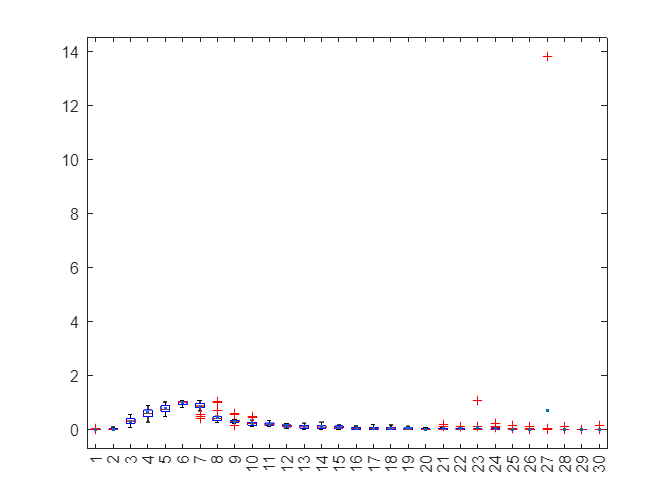



figure()
boxplot(coeff_bs_array)
hold on
plot(mean(coeff_bs_array),'.')

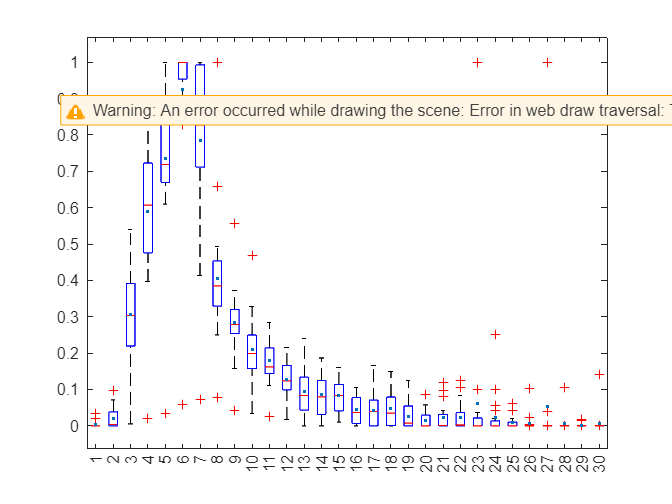


%% box
figure()
boxplot(coeff_bs_norm_array)
hold on
plot(mean(coeff_bs_norm_array),'.')


% flow index fitting parameters
beta_array_filt = beta_array(find(beta_array(:,2)> -9.99),:);

Index in position 2 exceeds array bounds.

## Output Table

results = [peaks_array,peak_time_array,insp_length_array, coeff_bs_norm_array]


## Generate general model consider median values

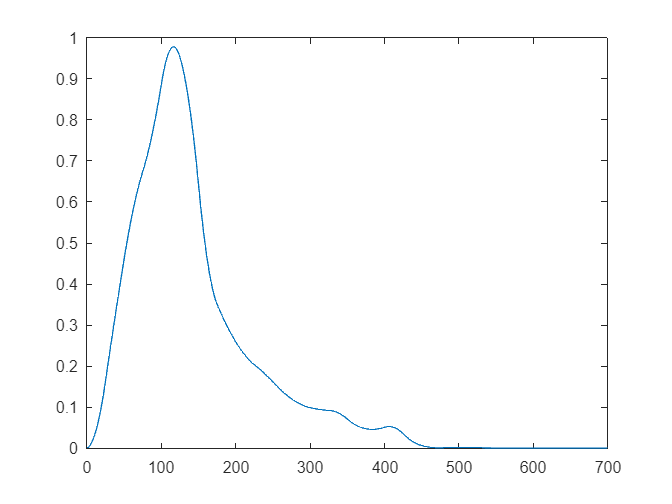

%length of breath
length_breath = 7;
%length_breath = length_vent_insp_array(counter,1)/100;
totalTime = [0.01:0.01:length_breath]; %create time vector equal to length of inspiratory effort

%create B-Spline model=
Kw = 0.25; %knot width, s
Tmax = Kw * ceil(length_breath/Kw); %Time span of B-spline functions
d = 3; %degree of B-splines
M = Tmax/Kw + d-1; %number of B-splines
%M = 10;
knots = 0:Kw:Tmax; %knot vector
knots = [0 0 0 knots Tmax Tmax Tmax]; %knot vector adding dummy values at start and end

phi_2 = zeros(cast(M,"int32"),length(totalTime));
for idx1 = 1:M
    phi_2(idx1,(1:length(totalTime))) = bspline_basis(idx1,3,knots,totalTime);
end
% median value of each normalised b-spline
coeff_med_norm = median(coeff_bs_array);
pmus_model = coeff_med_norm*phi_2;

figure()
%plot(pmus)
%hold on
plot(pmus_model)
hold on

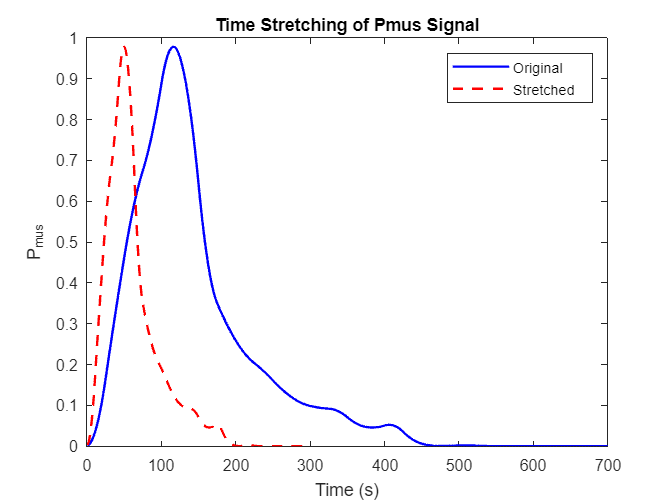

pmus_model_shorten = pmus_model(1:700); 

% renormalise length to 1 second
t_old = linspace(1,700,700);
t_new = linspace(1,300,700);

% Normalize time for interpolation
tau = t_old / 700;
tau_new = t_new / 300;

Pmus_stretched = interp1(tau, pmus_model_shorten, tau_new, 'spline');

% Plot
figure;
plot(t_old, pmus_model_shorten, 'b', 'LineWidth', 1.5); hold on;
plot(t_new, Pmus_stretched, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('P_{mus}');
legend('Original', 'Stretched');
title('Time Stretching of Pmus Signal');


% median value of each normalised b-spline
coeff_mean_norm = mean(coeff_bs_array);
pmus_model_2 = coeff_mean_norm*phi_2;

%figure()
%plot(pmus)
%hold on
plot(pmus_model_2)



## Fit Breaths using General Model

i = 1;
counter = 0;

%collect 20 breaths per patient
while counter < num_breaths +1

    %if i is less than total number of breaths
    if i <= length(volume_allBreaths)
        volume = volume_allBreaths{i};
        phase = phase_allBreaths{i};

        %if no end expiratory volume present
        if volume(1) < 500
            pmus = Pmus_inv_allBreaths{i};

            %shift pmus if neccessary
            if pmus(1) > 0.05 || pmus(1) < -0.05
                pmus = pmus - pmus(1);
            end

            pmus_model_temp = pmus_model;
            %only consider muscle pressure during vent inspiration + onset
            pmus = pmus(1:find(diff(phase) == 32)+1);

            %adjust for different lengths
            if length(pmus)>length(pmus_model)
                pmus_model_temp = [pmus_model_temp'; zeros(length(pmus)-length(pmus_model_temp),1)];
            else
                pmus_model_temp = pmus_model_temp(1:length(pmus));
            end

            %transpose model matrix if needed
            if size(pmus_model_temp) ~= size(pmus)
                pmus_model_temp = transpose(pmus_model_temp);
            end

            % Model Pmus using B-Splines
            lb = -50;
            ub = 0;
            mag_effort = lsqlin(pmus_model_temp,pmus',[],[],[],[],lb,ub);


            figure()
            plot(pmus)
            hold on
            plot(pmus_model_temp'*mag_effort)
            hold off
        end
        i = i+1;
    else
        break
        counter
    end
end

function pesFilter = pesFilterFun(dataSignals, sample_rate, F_cgo)

Fs = sample_rate;
%% SSA Technique
%% Set general Parameters
M = 3/2*sample_rate;    % window length = embedding dimension
N = length(dataSignals.pes);   % length of generated time series

%% Create time series X
% First of all, we generate a time series, a sine function of length N with
% observational white noise

t = (1:N)';
X = dataSignals.pes;
%% Calculate covariance matrix (trajectory approach)
% An alternative approach is to determine C directly from the scalar
% product of Y, the time-delayed embedding of X. Although this estimation
% of C does not give a Toeplitz structure, with the eigenvectors not being
% symmetric or antisymmetric, it ensures a positive semi-definite covariance
% matrix.

Y=zeros(N-M+1,M);
for m=1:M
    Y(:,m) = X((1:N-M+1)+m-1);
end
C=Y'*Y / (N-M+1);


%% Calculate eigenvalues LAMBDA and eigenvectors RHO
% In order to determine the eigenvalues and eigenvectors of C, we use the
% function EIG. This function returns two matrices, the matrix RHO with
% eigenvectors arranged in columns, and the matrix LAMBDA with eigenvalues
% along the diagonal.

[RHO,LAMBDA] = eig(C);
LAMBDA = diag(LAMBDA);               % extract the diagonal elements
[LAMBDA,ind]=sort(LAMBDA,'descend');
RHO = RHO(:,ind);                    % and eigenvectors


%% Calculate principal components PC
% The principal components are given as the scalar product between Y, the
% time-delayed embedding of X, and the eigenvectors RHO.

PC = Y*RHO;

%% Calculate reconstructed components RC
% In order to determine the reconstructed components RC, we have to invert
% the projecting PC = Y*RHO; i.e. RC = Y*RHO*RHO'=PC*RHO'. Averaging along
% anti-diagonals gives the RCs for the original input X.

RC=zeros(N,M);
for m=1:M
    buf=PC(:,m)*RHO(:,m)'; % invert projection
    buf=buf(end:-1:1,:);
    for n=1:N % anti-diagonal averaging
        RC(n,m)=mean( diag(buf,-(N-M+1)+n) );
    end
end

%filter RC's using zero phase 4th order butterworth band pass
%lower cutoff = 0.17 hz, upper cutoff = 1.4 hz

%butterworthbandpass filter
[b_1,a_1] = butter(4,1.4/(Fs/2));
RC_filter1 = filtfilt(b_1,a_1,RC);
%RC_filter1 = RC;
%filter RC's using zero phase 4th order butterworth notch filter
[z,p,k] = butter(4,[F_cgo-F_cgo/10,F_cgo+F_cgo/10]/(Fs/2),'stop');
[sos,g] = zp2sos(z,p,k);
%RC_filter2 = filtfilt(sos,g,RC_filter1);
RC_filter2 = RC_filter1;
%% Dynamic Weight Calculation
%filRC summing algorithm
Th_w = 0.9999;


rec = 0;
weigh = 0;
flag_opt = 0;
i= 1;

while flag_opt == 0
    rec = rec+RC_filter2(:,i);
    %weigh_n = (sum(RC_filter2(:,1)^2))/susum(RC_filter2(:,1)^2)
    num = 0;
    den = 0;

    for n=1:N
        num = num + RC_filter2(n, i)^2;
    end
    for m=1:M
        for n=1:N
            den = den + RC_filter2(n,m)^2;
        end
    end
    weigh_2 = num/den;

    weigh = weigh + weigh_2;

    if weigh > Th_w
        i_opt = i;
        dPeso = rec;
        flag_opt = 1;
    end
    i = i+1;
end

%% Outputs
pesFilter = dPeso;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
function [pesShiftedEachBreath,pes_filt_shift, pes_shift,Pmus_inv_allBreaths,volume_allBreaths,flow_allBreaths,paw_allBreaths,Pmus_inv_raw_allBreaths, phase_allBreaths] ...
    = startOfInspPatFun(dataSignals, Ecw, numBreaths)
%% Import Signals

pes = dataSignals.pes;
pes_filt = dataSignals.pes_filt;
phase = dataSignals.phase;
flow = dataSignals.flow;
paw = dataSignals.pres;
PEEP = dataSignals.PEEP;
%% Process Pes Signal

%shift start of signal to start from zero
pes_shift = pes - pes(1);
pes_filt_shift = pes_filt - pes_filt(1);

%find start of each inspiration
startInsp = find(diff(phase) == -32);
startInsp = startInsp + 1;

%find start of each expiration
endInsp = find(diff(phase) == 32);
endInsp = endInsp + 1;


ind_effort_start_array = zeros(length(startInsp),1);

for idx=2:length(endInsp)

    if idx <= length(startInsp)


        %extract data prior to triggering
        ind_back = 150;
        if startInsp(idx)<ind_back
            ind_back = startInsp(idx)-1;
        end
        %pes_section = pes_filt(startInsp(idx)-ind_back:startInsp(idx));
        paw_section = paw(startInsp(idx)-ind_back:startInsp(idx));
        %paw_section_reverse = flip(paw_section);

        ind_shoulder = find(paw_section == PEEP, 1,"last")
        % %rotate matrix to determine shoulder of pes (start of inspiration)
        % %determine gradient
        % theta = atan2((pes_section(end)-pes_section(1)),length(pes_section)-1)*180/pi;
        % 
        % rot_matrix = rotz(theta);
        % pes_matrix = [[1:1:length(pes_section)]',pes_section,ones(length(pes_section),1)];
        % pes_rot_matrix = pes_matrix*rot_matrix;
        % 
        % [~,ind_shoulder] = max(pes_rot_matrix(:,2));
        % 
        % %capture onset of effort in pes signal
        % pes_shift((startInsp(idx)-(ind_back-ind_shoulder)):end) = pes_shift((startInsp(idx)-(ind_back-ind_shoulder)):end)-pes_shift(startInsp(idx)-(ind_back-ind_shoulder));
        % pes_filt_shift((startInsp(idx)-(ind_back-ind_shoulder)):end) = pes_filt_shift((startInsp(idx)-(ind_back-ind_shoulder)):end)-pes_filt_shift(startInsp(idx)-(ind_back-ind_shoulder));
        % 
        % %save location of each pat
         ind_effort_start_array(idx) = ind_back-ind_shoulder;

    end
end

%% Store Signals
%save pes shifted signals between onset breath switching point and
%save signals between switching points
%save first breath
pesFiltShiftedEachBreath = cell(numBreaths,1);
pesShiftedEachBreath = cell(numBreaths,1);
Pmus_inv_allBreaths = cell(numBreaths,1);
Pmus_inv_raw_allBreaths = cell(numBreaths,1);
volume_allBreaths = cell(numBreaths,1);
flow_allBreaths = cell(numBreaths,1);
paw_allBreaths = cell(numBreaths,1);
phase_allBreaths = cell(numBreaths,1);

for idx=1:length(startInsp)-1

    pesFiltShiftedEachBreath{idx,1} = pes_filt_shift((startInsp(idx)-ind_effort_start_array(idx)):(startInsp(idx+1)-ind_effort_start_array(idx+1)));
    pesShiftedEachBreath{idx,1} = pes_shift((startInsp(idx)-ind_effort_start_array(idx)):(startInsp(idx+1)-ind_effort_start_array(idx+1)));
    phase_allBreaths{idx,1} = phase((startInsp(idx)-ind_effort_start_array(idx)):(startInsp(idx+1)-ind_effort_start_array(idx+1)));
    flow_allBreaths{idx,1} = flow((startInsp(idx)-ind_effort_start_array(idx)):(startInsp(idx+1)-ind_effort_start_array(idx+1)));
    volume_allBreaths{idx,1} = cumtrapz(flow_allBreaths{idx,1})/100;

    %invasive muscle pressure determination
    Pmus_inv_allBreaths{idx,1} = pesFiltShiftedEachBreath{idx,1} - (Ecw * volume_allBreaths{idx,1}/1000);
    Pmus_inv_raw_allBreaths{idx,1} = pesShiftedEachBreath{idx,1} - (Ecw * volume_allBreaths{idx,1}/1000);
    paw_allBreaths{idx,1} = paw((startInsp(idx)-ind_effort_start_array(idx)):(startInsp(idx+1)-ind_effort_start_array(idx+1)));
end



end

